tstep = 10000;
E_g = zeros(1,tstep);
a =  zeros(1,tstep);
b = zeros(1,tstep);
c = zeros(1,tstep);

% initialization
h = 50;
U = 0.1*randn(h,1);
V = 0.1*randn(h,1);
W_star = 0.1*randn();
W = (V'*U)';
Z = W'-W_star';
a(1,1) = V'*V;
b(1,1) = U'*U;
c(1,1) = Z*W;
E_g(1,1) = 0.5*Z^2;

% parameters
sigma1 = 0.01;
sigma2 = 0.01;
ita1 = 0.01/h;
ita2 = 0.01/h;

% recurrent relations 
for i = 1:1:(tstep-1)
    E_g(1,i+1) = (3*ita1^2*sigma2^2/sigma1^2+1)*E_g(1,i)-2*ita1*E_g(1,i)*a(1,i)-2*ita2*E_g(1,i)*b(1,i)...
        +(12*ita1*ita2+3*ita1^2*sigma2^2/sigma1^2)*E_g(1,i)*c(1,i)+12*ita1*ita2*a(1,i)*b(1,i)*E_g(1,i)...
        +(6*ita2^2*sigma1^2/sigma2^2)*a(1,i)*b(1,i)^2*E_g(1,i);
    a(1,i+1) = a(1,i)-2*ita2*c(1,i)+(6*ita2^2*sigma1^2/sigma2^2)*a(1,i)*b(1,i)*E_g(1,i);
    b(1,i+1) = b(1,i)-2*ita1*c(1,i)+(6*ita1^2*sigma2^2/sigma1^2)*E_g(1,i);
    c(1,i+1) = c(1,i)-2*ita1*E_g(1,i)*a(1,i)-2*ita2*E_g(1,i)*b(1,i)+12*ita1*ita2*E_g(1,i)*c(1,i)...
        -ita1*a(1,i)*c(1,i)-ita2*b(1,i)*c(1,i)+6*ita1*ita2*c(1,i)^2+(6*ita1^2*sigma2^2/sigma1^2)*E_g(1,i)...
        +24*ita1*ita2*a(1,i)*b(1,i)*E_g(1,i)+(6*ita2^2*sigma1^2/sigma2^2)*a(1,i)*b(1,i)^2*E_g(1,i);
end

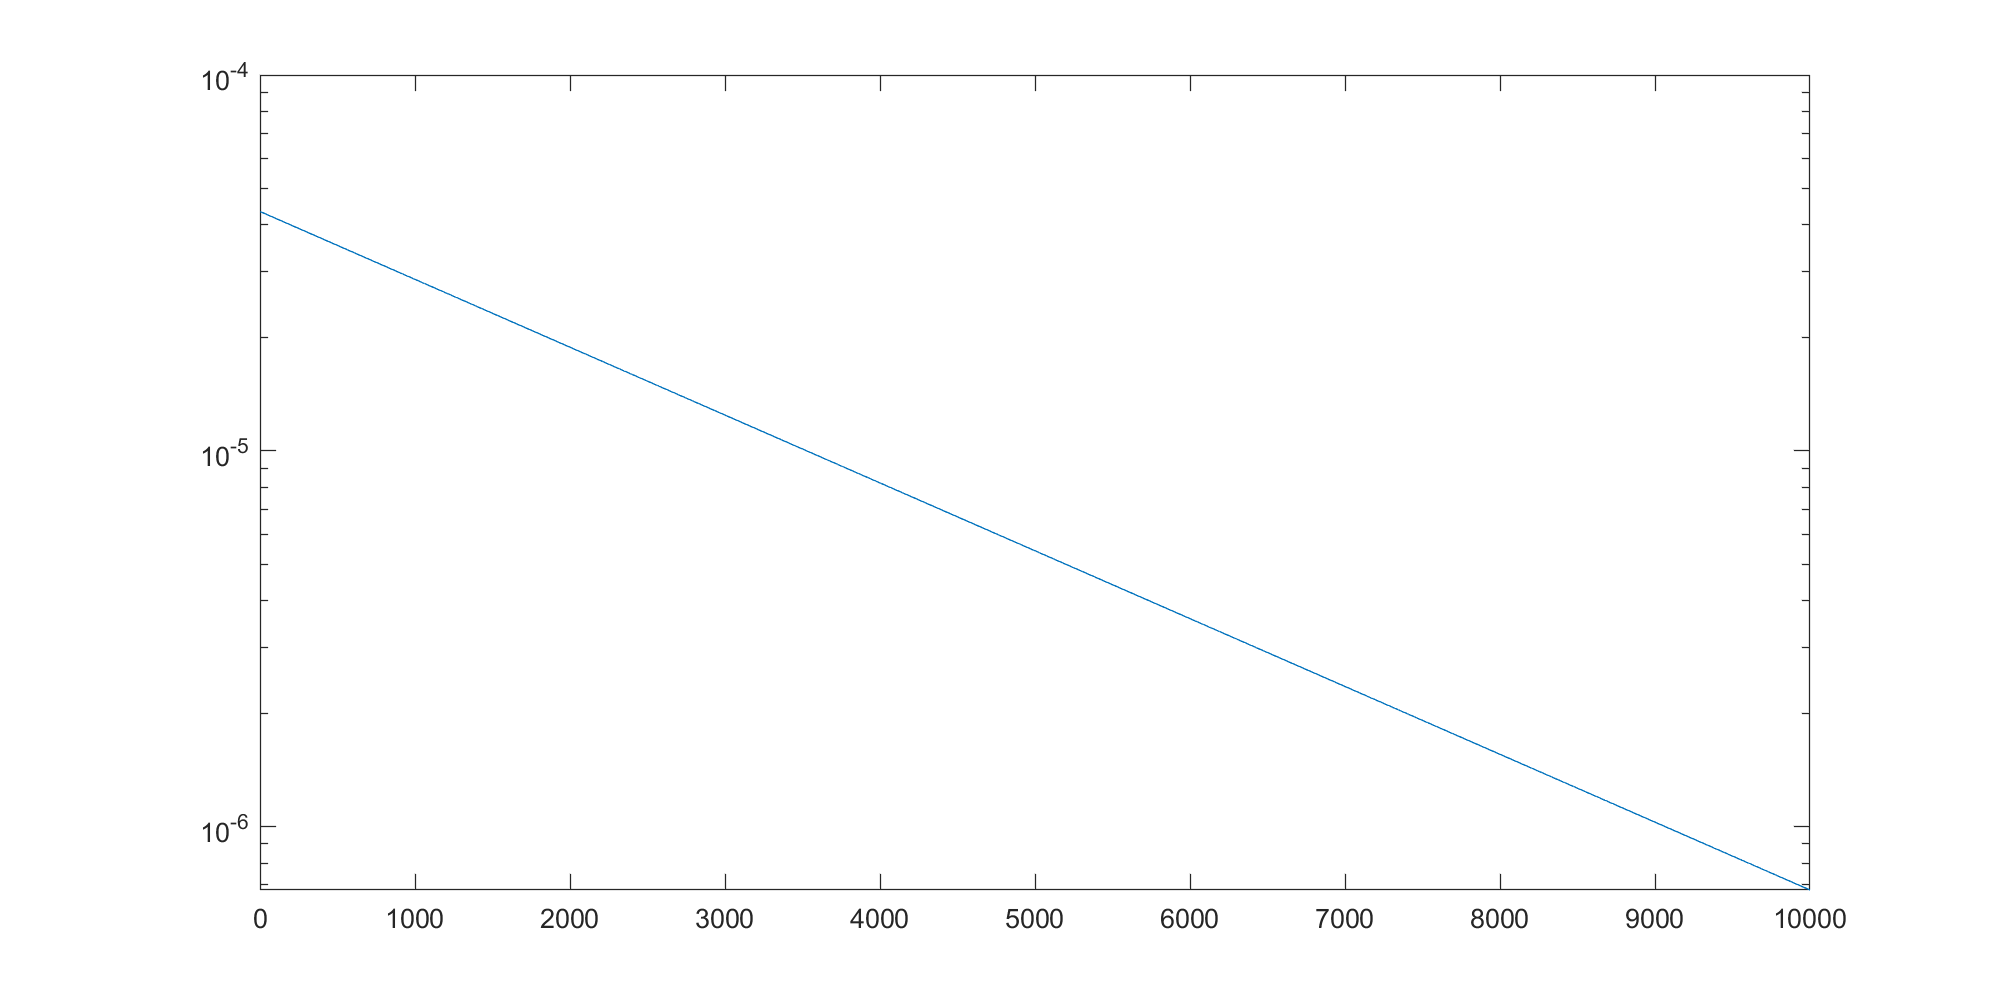

% plotting
figure
set(gcf, 'Position',  [100, 100, 1000, 500])
semilogy(E_g)

% subplot(4,1,2)
% plot(a)
% subplot(4,1,3)
% plot(b)
% subplot(4,1,4)
% plot(c)
